% =========================================================================
% 环路增益：K = Kd * K0 * Klpf
% Kd = 1/2 * Ui * U0,鉴相器增益，Ui:输入信号幅值，U0：LLP输出幅值
% K0 = fs/2^Bnco,VCO增益(Hz/V)
% Klpf:低通滤波器增益
% =========================================================================

## --- 参数初始化

fs = 10e3;      % 采样频率10KHz
fo = 400;       % LLP固有频率400Hz
df = 35;         % 初始频差Hz
fi = fo + df;   % 信号频率
Bnco = 32;              % 频率累加字位数32Bits
K0 = fs/2^Bnco;         % NCO增益(Hz/V),(频率控制灵敏度)

c1 = 2^(-1);     % 环路滤波器系数，在FPGA中为移位运算
c2 = 2^(-9);

lfout(1) = 0;    % 环路滤波器输出
temp  = 0;       % 环路滤波器中间变量

LLP_Phase_Index = 0;
PFout = 0;
LLP_Phase_init = fo * 2^Bnco / fs;  %初始VCO频率控制字

## --- 产生400Hz正弦波信号

L = 10000;  % 数据长度
N = 8;      % 量化位数
st = 0:1/fs:(L-1)/fs;
si = sin(2*pi*fi*st + pi/4);   % 生成Sin正弦信号
f_si = si/max(abs(si));        % 归一化处理
Q_si = round(f_si * (2^(N-1)-1)); % 量化处理，round取四舍五入
% figure;
% plot(st(1:1000),Q_si(1:1000));

## --- FIR低通滤波器设计

Blpf = 8;                   % 滤波器系数量化
fc  = [300 600];            % 过渡带
band_amplitude = [1 0];     % 窗函数幅度
dev = [0.05 0.05];          % 带内纹波

[n,Wn,beta,ftype] = kaiserord(fc,band_amplitude,dev,fs);           % 获取kaiser参数，返回滤波器阶数n，标准化频带边缘 Wn，形状因子beta
h_kaiser = fir1(n,Wn,ftype,kaiser(n+1,beta));           % 获取滤波器系数
qh = round(h_kaiser/max(abs(h_kaiser))*(2^(Blpf-1)-1)); % 滤波器系数量化
qh_max = max(abs(qh));

Klpf   = qh_max / max(h_kaiser);   %计算滤波器增益
% sum_qh = sum(abs(qh));
% figure;
% freqz(h_kaiser,1);  %低通滤波器响应
% title('LPF滤波器响应');

K = 1/2 * 2^7 * 2^7 * K0 * Klpf;    %环路增益

%乘法运算输出信号初值
mult = zeros(1,L);
%鉴相器输出信号初值
pd = zeros(1,L);
lfout(n) = 0;
lfout(n+1) = 0;
pd(n)=0;

f=zeros(1,L);

% wn = sqrt(K/t1);

## --- DDS查找表

SinTableLength = 2^10;   % DDS的sin表的长度1024
SinTableAmp    = 2^7-1;  % DDS的sin表的最大幅度，为8位有符号量化
t = 2*pi*(0:SinTableLength - 1)/SinTableLength;
sin_table = floor(sin(t) * SinTableAmp);
cos_table = floor(cos(t) * SinTableAmp);
%DDS相位累加字为32位，而实际存储表为1024个，需要比列缩减
sin_table_Index_Scale = SinTableLength / (2^Bnco);

## --- 鉴相过程

for i=(1+n):L
    
    DDS_Phase_Index_Table = floor(LLP_Phase_Index * sin_table_Index_Scale) + 1;
    sin_nco(i) = sin_table(DDS_Phase_Index_Table);  %产生本地参考信号的I之路
    cos_nco(i) = cos_table(DDS_Phase_Index_Table);  %产生本地参考信号的Q之路
    
    mult(i) = Q_si(i)*cos_nco(i);   % PD乘法器
    %滤除相乘产生的高频分量
    PFout = filter(qh,1,mult(i-n:i)); %理解滤波器的工作原理，防止错误使用
    len = length(PFout);
    %鉴相器输出
    pd(i) = PFout(len);
    
    % 计算时频
    y=fft(cos_nco(i-n:i),L);
    [m,p]=max(abs(y));
    f(i)=p*fs/L;
    
    %环路滤波器，（根据环路滤波器传递函数）
    lfout(i) = lfout(i-1) + c1*pd(i) + (c2-c1)*pd(i-1);
    lfout1 = temp + c1*pd(i);
    temp  = temp + c2*pd(i);
    % 查表法索引
    LLP_Phase_Index = LLP_Phase_Index +LLP_Phase_init + lfout1;  % 环路NCO累积，产生本地参考信号
    
    if(LLP_Phase_Index < 0)
        LLP_Phase_Index = 0;
    end
    if(LLP_Phase_Index >= 2^Bnco)
        LLP_Phase_Index = LLP_Phase_Index - 2^Bnco;
    end
end

## --- 显示

figure; y2=fft(sin_nco); p2=angle(y2); phase=p2*180/pi; plot(phase(1:5000)); figure; plot(lfout*pi/fs/180);

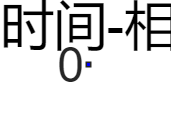

figure;
plot(pd/fs/SinTableAmp,'b');
title('鉴相器输出(时间-相位差示意图)');
xlabel('时间(t/s)');ylabel('相位差(rad)');
xticklabels([0:1/10:1]);

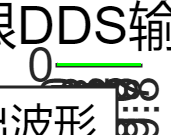


figure;
hold on;
plot(sin_nco(1:8000)/SinTableAmp,'-k');   % 输出波形
hold on;
plot(Q_si(1:8000)/SinTableAmp,'-g');      % 原始输入信号波形
legend('输出波形', '原始波形')
title('原始信号跟DDS输出波形对比');
xlabel('时间(t/s)');
xticklabels([0:1/10:1]);

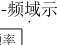



x=zeros(1,L);
z=fft(Q_si,L);
[a,b]=max(abs(z));
x(1:L)=b*fs/L;

figure;
hold on;
plot(f(1:5000),'-r');
hold on;
plot(x(1:5000),'-b');
title('时域-频域示意图');
legend('输出频率', '参考频率')
xlabel('时间(t/s)');ylabel('频率(f/Hz)');
xticklabels([0:1/10:1]);

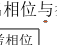


figure;
phin = 2*pi*fi*st + pi/4;

pvco=phin-pd/fs;
t1 = 1:1:10000;
plot(t1,phin/SinTableAmp,t1,pvco/SinTableAmp)
title('输出相位与参考相位')
legend('参考相位', '输出相位')
xlabel('时间(t/s)');ylabel('相位(rad)');
xticklabels([0:1/10:1]);